% 目的：找到FRF求解方法
% 文献：Flexural wave propagation in beams with periodically attached vibration absorbers: Band-gap behavior and band formation mechanisms
% 
% 状态：不需要继续
% 备注：将Xiao文献中的铝梁参数换到Dutkiewicz文献中，观察能否成功计算FRF
% ================================================

## 参数设置

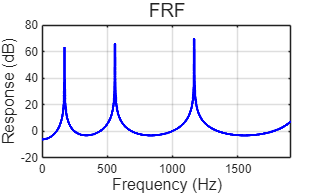


clear; clc;
%%
% 
% %% 1. 几何参数 (Table 1)
% geometry.h = 0.015;      % 梁高度 [m]
% geometry.l = 0.01;       % 间距 [m]
% geometry.r1 = 0.013;     % 内半径 [m]
% geometry.r2 = 0.015;     % 中间半径 [m]
% geometry.r3 = 0.018;     % 外半径 [m]
% geometry.L = 0.1;        % 梁总长度 [m]
% geometry.N = 6;         % 单元个数
% 
% %% 2. 材料参数 (Table 2)
% % 铝层参数
%     material.aluminum.E = 7e10;          % 杨氏模量 [Pa]
% material.aluminum.G = 2.7e10;        % 剪切模量 [Pa]
%     material.aluminum.rho = 2700;        % 密度 [kg/m^3]
% 
% 
% %% 3. 截面特性计算
% % 梁的横截面积
%     geometry.A = pi*(geometry.r3^2-geometry.r2^2);
% % 梁的惯性矩
% geometry.I = pi*(geometry.r3^4-geometry.r2^4)/4;

%%

% 几何参数
    geometry.r1 = 0.013;     % 内半径 [m]
    geometry.r2 = 0.015;     % 中间半径 [m]
    geometry.r3 = 0.018;     % 外半径 [m]

% 材料参数
    material.E = 7e10;       % 索的弹性模量 (Pa)
% material.ita = 0.01;       % 阻尼
    material.rho = 2700;       % 索的密度 (kg/m³)
    material.A = pi*(geometry.r3^2-geometry.r2^2);       % 索的截面积 (m2)
    material.m = material.rho * material.A;        % 索的每延米质量 (kg/m)
    material.D = sqrt(4 * material.A / pi());    % 索的直径 (m)
    material.L = 0.6;        % 索的长度 (m)
    material.T = 0;         % 索的张力 (N)
    material.I = pi * material.D^4 / 64;  % 索的惯性矩 (m⁴)
    material.EI = material.E * material.I;

% 单元划分
n_elements = 3;  % 3个单元，适当增加以避免振型丢失
element_length = material.L / n_elements;  % 每个单元长度

% 频率范围设置
omega_values = linspace(0.1, 12000, 12000);
fre = omega_values ./ (2*pi());
H_values = zeros(size(omega_values));

% 激励和响应位置设置
excitation_dof = 1;  % 激励节点
response_dof = 2*(n_elements+1)-1;    % 响应节点

% 检查波束随频率变化，后续画图观察
k_record = zeros(size(omega_values));

for i = 1:length(omega_values)
    omega = omega_values(i);
    
    % 初始化全局矩阵 (4节点，每个节点有2个自由度)
    global_dof = 2*(n_elements+1);
    K_global = zeros(global_dof, global_dof);
    
    % 组装每个单元的矩阵
    for elem = 1:n_elements
        % 获取单元局部矩阵
        [S_local, k_record(i)] = spetral_element_matrix(omega, material, element_length);
        
        % 计算全局自由度索引
        start_dof = 2*(elem-1)+1;
        end_dof = start_dof + 3;
        
        % 组装到全局矩阵
        K_global(start_dof:end_dof, start_dof:end_dof) = ...
            K_global(start_dof:end_dof, start_dof:end_dof) + S_local;
    end
    
    % 已知条件：左端点位移 = 1
    known_disp_dof = excitation_dof; % 位移已知的自由度
    unknown_dofs = setdiff(1:global_dof, known_disp_dof); % 其他自由度
    
    % 分区处理系统方程
    K_kk = K_global(known_disp_dof, known_disp_dof);
    K_ku = K_global(known_disp_dof, unknown_dofs);
    K_uk = K_global(unknown_dofs, known_disp_dof);
    K_uu = K_global(unknown_dofs, unknown_dofs);

    % 已知位移条件
    U_k = 1; % 左端点单位位移激励

    % 求解未知位移
    % K_uu * U_u = -K_uk * U_k
    U_u = K_uu \ (-K_uk * U_k);
    
    % 组装完整的位移向量
    U_full = zeros(global_dof, 1);
    U_full(known_disp_dof) = U_k;
    U_full(unknown_dofs) = U_u;

    % 提取输入和输出位移
    U_in = U_full(excitation_dof);
    U_out = U_full(response_dof);

    T_N = abs(U_out / U_in);
    H_values(i) = 20 * log10(abs(T_N));

end

% 绘制频响函数
plot_FRF(fre, H_values);

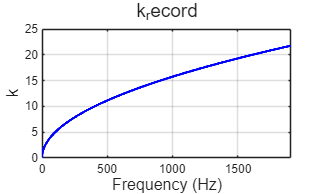


plot_k(fre,k_record);



% 谱元矩阵函数
function [S,k] = spetral_element_matrix(omega, material, L)
    % 计算波数 k (公式5)
    alpha = material.T / (2 * material.EI);
    beta = material.m / material.EI;
    % 计算波数
    k = sqrt(sqrt(alpha^2 + beta * omega^2) - alpha);
    
    % 计算矩阵元素
    [s11, s12, s13, s14, s22, s23, s24] = calculate_matrix_elements(k, L);
   
    % 计算Delta
    delta = cos(k*L) .* cosh(k*L) - 1;
    
    % 构建对称矩阵
    S = material.EI ./ delta .* [ ...
        s11,  s12,  s13,  s14; ...
        s12,  s22,  s23,  s24; ...
        s13,  s23,  s11, -s12; ...  % s33 = s11, s34 = -s12
        s14,  s24, -s12,  s22  ...  % s44 = s22
    ];
end

function [s11, s12, s13, s14, s22, s23, s24] = calculate_matrix_elements(k, L)
    s11 = -k.^3 .* (cos(k*L).*sinh(k*L) + sin(k*L).*cosh(k*L));
    s12 = -k.^2 .* sin(k*L) .* sinh(k*L);
    s13 = k.^3 .* (sin(k*L) + sinh(k*L));
    s14 = k.^2 .* (cos(k*L) - cosh(k*L));
    s22 = k .* (cos(k*L).*sinh(k*L) - sin(k*L).*cosh(k*L));
    s23 = k.^2 .* (cosh(k*L) - cos(k*L));
    s24 = k .* (sin(k*L) - sinh(k*L));
end

function plot_FRF(fre, H_values)
    figure;
    plot(fre, H_values, 'b-', 'LineWidth', 2);

    xlabel('Frequency (Hz)', 'FontSize', 12);
    ylabel('Response (dB)', 'FontSize', 12);
    title(sprintf('FRF'), ...
        'FontSize', 14);
    grid on;
    xlim([0 max(fre)]);
end

function plot_k(fre, k_record)
    figure;
    plot(fre, k_record, 'b-', 'LineWidth', 2);

    xlabel('Frequency (Hz)', 'FontSize', 12);
    ylabel('k', 'FontSize', 12);
    title(sprintf('k_record'), ...
        'FontSize', 14);
    grid on;
    xlim([0 max(fre)]);
end

